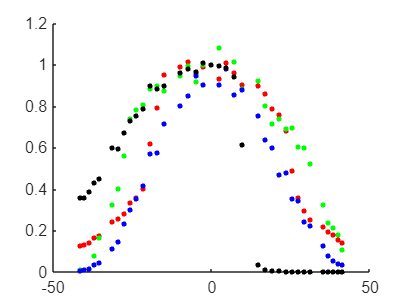

% Position and angle matrices
position_mid = [0.9,1.8,2.7,3.6];
position_side = 0.9*(0:8)+5.6;
position_out = 0.9*(0:4)+15;
positions = [-flip(position_out), -flip(position_side), -flip(position_mid), 0, position_mid, position_side, position_out];
theta1 = atan(positions/21.15)*180/pi;
theta1 = theta1';

% Get data and scale the different integration times
WHITE_100_Angles_Further_Scaled = scale(WHITE_100_Angles_Further);
W_100_Further_M = transpose(reshape(cell2mat(WHITE_100_Angles_Further_Scaled(:,3)),9,15));
WHITE_100_Angles_Further_L_Scaled = scale2(WHITE_100_Angles_Further_L);
W_100_Further_L = transpose(reshape(cell2mat(WHITE_100_Angles_Further_L_Scaled(:,3)),[],15));
WHITE_100_Angles_Further_R_Scaled = scale2(WHITE_100_Angles_Further_R);
W_100_Further_R = transpose(reshape(cell2mat(WHITE_100_Angles_Further_R_Scaled(:,3)),[],15));

W_100_Further = [W_100_Further_R, W_100_Further_M, W_100_Further_L];

W_100_Further_normaliseW_AS = W_100_Further(1:9,:)./W_100_Further(1:9,19);
W_100_Further_normaliseW_VEML = W_100_Further(11:14,:)./W_100_Further(11:14,19);

% AS7341 Colour scatter
scatter(theta1, W_100_Further_normaliseW_AS([7, 4, 2, 9],:),10, VEML_Colours, 'filled')
hold on
% scatter(theta, W_100_normaliseW_AS(:,[7, 4, 2, 9]),5,"cyan")
hold off

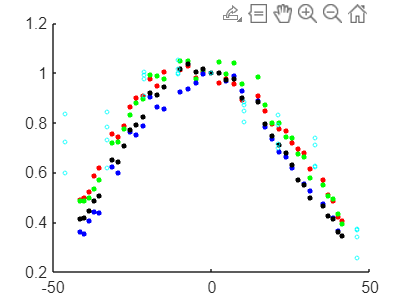

% scatter(theta1, W_100_Further_normaliseW_AS(7,:), [], 'red')
% scatter(theta1, W_100_Further_normaliseW_AS(4,:), [], 'green')
% scatter(theta1, W_100_Further_normaliseW_AS(2,:), [], 'blue')

% VEML6040 Colour scatter
scatter(theta1, W_100_Further_normaliseW_VEML(1:4,:), 10, VEML_Colours, 'filled')
hold on
scatter(theta, W_100_normaliseW_VEML(:,1:4),5,"cyan")
hold off

% scatter(theta1, W_100_Further_normaliseW_VEML(1,:), [], 'red')
% scatter(theta1, W_100_Further_normaliseW_VEML(2,:), [], 'green')
% scatter(theta1, W_100_Further_normaliseW_VEML(3,:), [], 'blue')

function COLOUR_Scaled = scale(COLOUR)
    factors = [4, 2, 1, 0.5, 0.25, 0.125];
    COLOUR_Scaled = cell(9,4);
    for j = 1:9
        for i = 1:4
            COLOUR_Scaled{j,i} = COLOUR{j, i}.*factors(i);
        end
    end
end

function COLOUR_Scaled = scale2(COLOUR)
    factors = [4, 2, 1, 0.5, 0.25, 0.125];
    COLOUR_Scaled = cell(14,4);
    for j = 1:14
        for i = 1:4
            COLOUR_Scaled{j,i} = COLOUR{j, i}.*factors(i);
        end
    end
end